Use MATLAB to repeat Example 3.7 for N=50 and (a) M = 12, (b) M=5, and (c) M=20

Example 3.7: Building A Square Wave From DTFS Coefficients

The contribution of each term to the square wave may be illustrated by defining the partial-sum approximation to x[n] in Eq. (3.17) as 

    xhat_J[n] = sum(k==0 to J) [ B[k] cos(k Omega_0 n), where J<= N/2. This approximation contains the first 2J +1 terms centered on k=0 in Eq. (3.10). Assume a square wave has period N=50, M=12. Evaluate on period of the Jth term in Eq. (3.18) and 2J+1 term approximation xhat_J[n] for J = 1,3,5,23,25. 

From page 208-210: 

Square wave: x[n] = { 1, -M <= n <= M    ;     { 0, M < n < N -M

X[k] = 1/N * (sin(k *pi (2M+1)/N))/(sin(k * pi / N)) for k not equal to 0, +-N, +-2N

= (2M+1)/N for k equal to 0, +-N, +-2N

## Slide 1

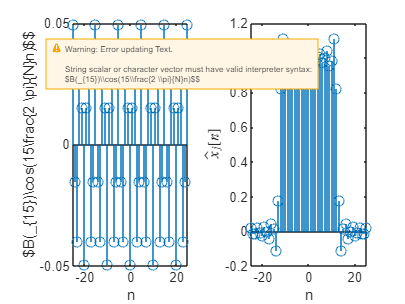

clear
N = 50;   % period of the square wave
M = 12;   % M * 2 + 1 = number of pulses in one period
k = 0:N/2;      % range of k values in eq. 3.17
n = -N/2:N/2;   % one period of values of the independent variable n

X = 1/N*sin(k*pi*(2*M+1)/N)./sin(k*pi/N);   % DTFS coef. X[k], k = 0,1,...,N/2
X(1) = (2*M+1)/N;                           % DTFS coef. X[k], k = 0

B = 2*X;                 % B[k] = 2 * X[k], k = 1, 2, ..., N/2 - 1
B(1) = X(1);             % B[k] = X[k], k = 0
B(N/2+1) = X(N/2+1);     % B[k] = x[k], k = N/2

x_hat_j = 0;      % Partial sum approximation to x[n]
jay = 15;
for k = 0:jay
    Bcosj = B(k+1)*cos(k*2*pi/N*n);   % Jth term in the sum
    x_hat_j = x_hat_j + Bcosj;
end

figure(1)
subplot(1,2,1)
stem(n,Bcosj)
xlabel('n')
y_str = sprintf('$%s_{%i}%s%i%s$', 'B(', jay, ')\cos(', jay, '\frac{2 \pi}{N}n)$');
ylabel(y_str,'Interpreter','latex')

subplot(1,2,2)
stem(n,x_hat_j)
xlabel('n')
ylabel('$\hat{x}_j[n]$','Interpreter','latex')

## Slide 2

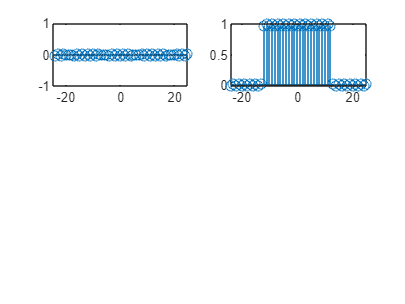

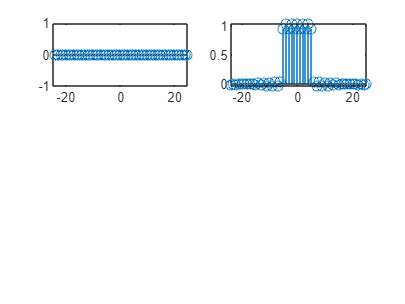

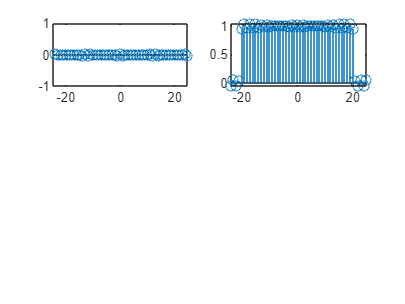

clear
N = 50;
MM = [12,5,20];
n = -24:25;

for p = 1:3      % for each M value
    J = 23;
    M = MM(p);
    x = zeros(size(n));
    
    for k = 0:J
        Xk = 0;
        if (k == 0 || k == N)
            Xk = (2*M+1)/N;
        else
            Xk = sin(k*pi*(2*M+1)/N)/(N*sin(k*pi/N));
        end
        
        if (k == 0 || k == N/2)
            Bk = Xk;
        else
            Bk = 2 * Xk;
        end
        
        xharm = Bk*cos((k*2*pi/N)*n);
        x = x + xharm;
        
        if k == 3
            % plot
        elseif k == 5
            % plot
        end
    end
    
    figure(p)
    clf
    subplot(3,2,1)
    stem(n,xharm)
    axis([-N/2 N/2 -1 1])
    
    subplot(3,2,2)
    stem(n,x)
end